addpath(genpath('/datascience/projects/statisticallyfit/github/MATLAB/MatlabTutorial/AMTH250_NumericalMatlab/Numerical Analysis/Root Finding/'))

Question 1

n = 31, nMax = 100, solution = 0.739085


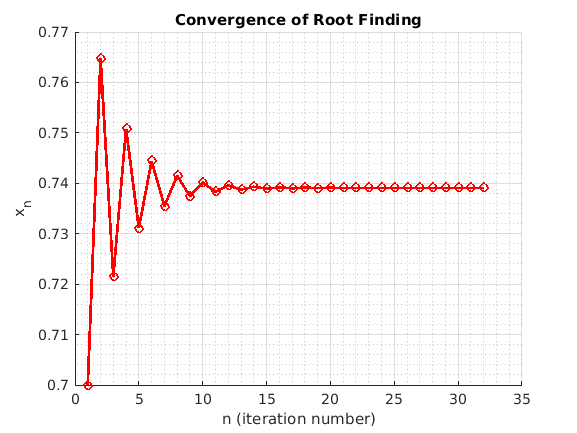

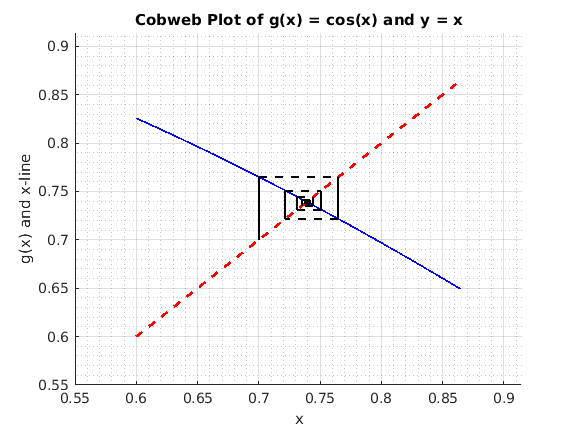

g = @(x) cos(x);
fixedPointP(g, 0.7, 6);

Question 2

f=  @(x) x.^4 - x - 0.12

f = function_handle with value:
    @(x)x.^4-x-0.12

n = 36, nMax = 36, solution = -0.1197940598


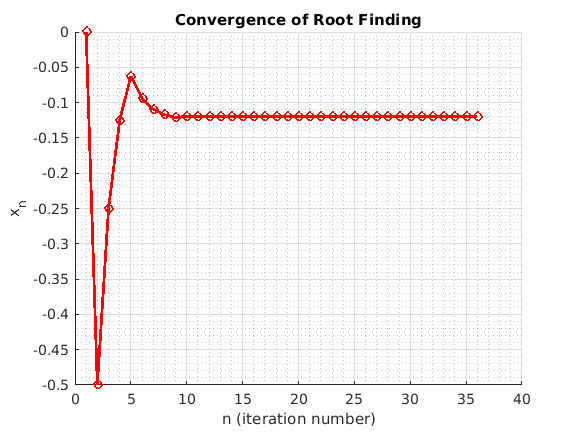

bisectP(f, -1, 1, 10);

g = @(x) x.^4 - 0.12
fixedPointP(g, 0, 8);

convergence is fast since graph near the solution is almost horizontal so |g'(x0)| is very small

% lipshutz continuous function. 
g = @(x) 0.12 ./ (x .^ 3 - 1);
fixedPointP(g, 2, 8);

Question 3

% when x0 = 0, then 0 < a < 1 for 
% convergence. WHen 0 < a< 1, xSOl = 0
a = 0.7;
g = @(x) a*x.*(1-x);
fixedPointP(g, 0.75, 6);

a = 0.5;
g = @(x) a*x.*(1-x);
fixedPointP(g, 0.75, 10);

% when x0 = (a-1)/a, then 1 < a < 3
% for convergence of fixed point. 
a = 1.1;
g = @(x) a*x.*(1-x);
fixedPointP(g, 0.1, 10);
% real sol = x = (a-1)/a = 0.090909.

a = 2;
g = @(x) a*x.*(1-x);
fixedPointP(g, 0.75, 6);
% real sol = x = (a-1)/a = 1/2

Now there is no convergence outside these bounds but choosing a >= 3 something interesting happens, if we first remove fluctuations. 

[s, x, g] = logisticMapCase(3.2);
plotCobweb(g, x)

[~, x, g] = logisticMapCase(3.5);
plotCobweb(g, x);

[~, x, g] = logisticMapCase(3.55);
plotCobweb(g, x);

[~, x, g] = logisticMapCase(3.7);
plotCobweb(g, x);

 Question 4

For x < 0: complete divergence = going to -Inf and then Inf right after. Then NaNs all the way. 

g = @(x) 1 - 5*x + (15/2)*x.^2-(5/2)*x.^3;
[sol, x] = fixedPointP(g, -0.2, 10);

plotCobwebInterval(g, -2, 2, -0.2);
plotConvergence(x);

For x -> 0- (zero from the left) we get a cycle near solution of x = 1.7745. (see where all the black is)

[sol, x] = fixedPointP(g, -0.01, 10);

plotCobwebInterval(g, -2, 2, -0.01);

plotConvergence(x);

For 0 < x < 1 (still no solution)

for x -> 0+

[~, x] = fixedPointP(g, 0.01, 10);
plotCobwebInterval(g, -2,2, 0.01);

plotConvergence(x);

for x -> 1- (to 1 from the left) we get cycle around the value x = 0.2255

[~, x] = fixedPointP(g, 0.99, 10);

plotCobwebInterval(g, -2,2, 0.99);

plotConvergence(x);

For 1 < x < 2 (for x -> 2- from the left, we get cycle around x = 1.7745)

[~, x] = fixedPointP(g, 1.9, 10);
plotCobwebInterval(g, -2, 2, 1.9)

% for x -> 1 from the right we still get cyle
% around 1.7745
plotCobwebInterval(g, -2, 2.5, 1.1)

plotConvergence(x)

For x > 2 (to 2 from the right, we get cycle around 0.225)

[~, x] = fixedPointP(g, 2.1, 10);
plotCobwebInterval(g, -2, 2, 2.1)

For x > 2 but increasing, we get Inf (so positive divergence)

[~, x] = fixedPointP(g, 2.2, 10);
plotCobwebInterval(g, -2, 2, 2.2)

plotConvergence(x) % even though it shows negative
% here it actually is going to Inf. 